## ME5106 Assignment 1 Group 3

#### General Information

% Title: ME5106.mlx
% Description: Assignment 1 Group 3
% MATLAB: R2022a Update 4 (9.12.0.2009381)
% Author: Xiao Ziheng
% Date: 19 Sep 2022


#### Emptying the command window and workspace

clear;
clc;


#### Filename extraction

% Filename extraction in the folder
DirFiles = dir(fullfile('.\01_RawData\', '*.xlsx'));
FileName = {DirFiles.name}';
MaxFileNum = length(FileName);

% File number
FileNum =11;

% Basic file name
BasicName = FileName{FileNum}(1:end-5)

BasicName = 'panasonicEH-ND11_heat2_8.5ms'

#### Data standardisation pre-processing

% File path
RawFileName = ['.\01_RawData\', BasicName, '.xlsx'];
ProFileName = ['.\02_UsingData\', BasicName, '.xls'];

% Read raw *.xlsx file into cell arrays
RawData = readcell(RawFileName);

% Delete the first two lines
RawData(1:2, :) = [];
% Convert a cell with no content to ' '
RawData(cellfun(@(x) any(ismissing(x)), RawData)) = {''};
% Get the cell array row and column sizes
[Rows, Cols] = size(RawData);
% Delete the no content columns
for index = 1:Cols
   if strcmp(RawData(2, (Cols - index +1)), '')
       RawData(:, (Cols - index + 1)) = [];
   end
end

% Re-add the column name to the first row
ColNames = {'X [s]','Real [Pa]',...
    'X [s]','Real [Pa]',...
    'X [Hz]','dB [Ref 2.00e-05 Pa]',...
    'X [Hz]','dB [Ref 2.00e-05 Pa]'};
RawData = [ColNames; RawData]

RawData = 16001×8 cell array
    {'X [s]'  }    {'Real [Pa]'}    {'X [s]'  }    {'Real [Pa]'}    {'X [Hz]' }    {'dB [Ref 2.00e-05 Pa]'}    {'X [Hz]' }    {'dB [Ref 2.00e-05 Pa]'}
    {[20.8800]}    {[   0.8034]}    {[20.8800]}    {[  -0.0772]}    {[      1]}    {[                -600]}    {[      1]}    {[                -600]}
    {[20.8812]}    {[  -1.1421]}    {[20.8812]}    {[  -0.6791]}    {[ 1.2589]}    {[                -600]}    {[ 1.2589]}    {[                -600]}
    {[20.8825]}    {[  -1.3388]}    {[20.8825]}    {[   0.2338]}    {[ 1.5849]}    {[                -600]}    {[ 1.5849]}    {[                -600]}
    {[20.8837]}    {[   1.1669]}    {[20.8837]}    {[  -0.8130]}    {[ 1.9953]}    {[                -600]}    {[ 1.9953]}    {[                -600]}
    {[20.8850]}    {[   0.7165]}    {[20.8850]}    {[   0.0228]}    {[ 2.5119]}    {[                -600]}    {[ 2.5119]}    {[                -600]}
    {[20.8862]}    {[  -1.1009]}    {[20.8862]}    {[  -0.6818]} 

% Add one to the total number of rows for the additional header
Rows = Rows + 1;

% Save the processed cell array file
xlswrite(ProFileName, RawData); %#ok<XLSWT> 


#### Basic image plotting of raw data

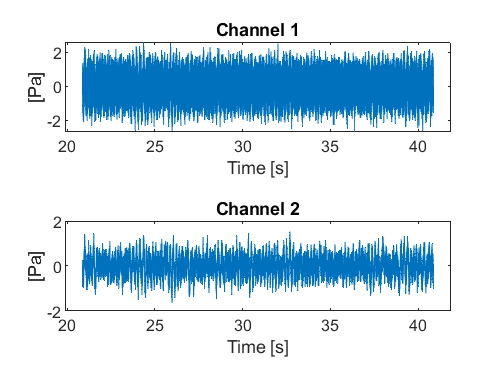

% New figure
figure
% Defining image layout
tiledlayout(2,1);

% Time history channel 1
plot(nexttile, cell2mat(RawData(2:Rows, 1)), cell2mat(RawData(2:Rows, 2)))

% Title
title('Channel 1');
% X-axis and y-axis labels
xlabel('Time [s]');
ylabel('[Pa]');
% X-axis range
xlim([(cell2mat(RawData(2, 1))-1) (cell2mat(RawData(Rows, 1))+1)]);

% Time history channel 2
plot(nexttile, cell2mat(RawData(2:Rows, 3)), cell2mat(RawData(2:Rows, 4)))

% Title
title('Channel 2');
% X-axis and y-axis labels
xlabel('Time [s]');
ylabel('[Pa]');
% X-axis range
xlim([(cell2mat(RawData(2, 1))-1) (cell2mat(RawData(Rows, 1))+1)]);

% Save the figure
SaveFigName = ['.\03_RawFigure\', BasicName, '_01', '.png'];
saveas(gcf, SaveFigName);

#### Basic image plotting of raw data (continued)

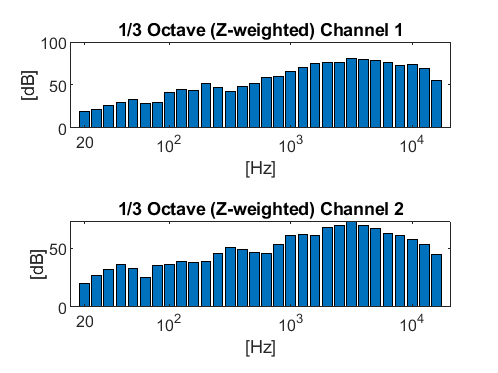

% New figure
figure
% Defining image layout
tiledlayout(2,1);

% 1/3 Oct Channel 1
bar(nexttile, cell2mat(RawData(15:44, 6)))

% X-axis ticks and positions
xticks([1 8 18 28]);
xticklabels({'20', '10^2','10^3','10^4'});

% Title
title('1/3 Octave (Z-weighted) Channel 1');
% X-axis and y-axis labels
xlabel('[Hz]');
ylabel('[dB]');

% 1/3 Oct Channel 2
bar(nexttile, cell2mat(RawData(15:44, 8)))

% X-axis ticks and positions
xticks([1 8 18 28]);
xticklabels({'20', '10^2','10^3','10^4'});

% Title
title('1/3 Octave (Z-weighted) Channel 2');
% X-axis and y-axis labels
xlabel('[Hz]');
ylabel('[dB]');

% Save the figure
SaveFigName = ['.\03_RawFigure\', BasicName, '_02', '.png'];
saveas(gcf, SaveFigName);

#### Sound pressure level

% Reference sound pressure (in air)
Pref = 2e-5;
% MEMS microphone Maximum Sound Pressure Level
% Since the experiment was calibrated before, there was no need to consider Laop
Laop = 0;

% Channel 1
% Effective sound pressure (i.e. Root Mean Square (RMS))
Pe_CH1 = rms(cell2mat(RawData(2:Rows, 2)))

Pe_CH1 = 1.1990

% Sound pressure level
SPL_CH1 = 20 * log10(Pe_CH1 / Pref) + Laop

SPL_CH1 = 95.5560


% Channel 2
% Effective sound pressure (i.e. Root Mean Square (RMS))
Pe_CH2 = rms(cell2mat(RawData(2:Rows, 4)))

Pe_CH2 = 0.4906

% Sound pressure level
SPL_CH2 = 20 * log10(Pe_CH2 / Pref) + Laop

SPL_CH2 = 87.7945

#### Calculate 1/3 Octave

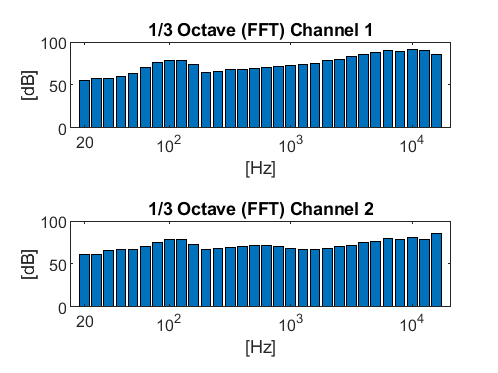

% New figure
figure
% Defining image layout
tiledlayout(2,1);

% Use FFT to convert time domain to frequency domain
[~, Oct_SPL, ~, ~] = tf_octave(cell2mat(RawData(2:Rows, 1:2)), 16000);

% 1/3 Oct Channel 1
bar(nexttile, Oct_SPL)

% X-axis ticks and positions
xticks([1 8 18 28]);
xticklabels({'20', '10^2','10^3','10^4'});

% Title
title('1/3 Octave (FFT) Channel 1');
% X-axis and y-axis labels
xlabel('[Hz]');
ylabel('[dB]');

% Use FFT to convert time domain to frequency domain
[~, Oct_SPL, ~, ~] = tf_octave(cell2mat(RawData(2:Rows, 3:4)), 16000);

% 1/3 Oct Channel 1
bar(nexttile, Oct_SPL)

% X-axis ticks and positions
xticks([1 8 18 28]);
xticklabels({'20', '10^2','10^3','10^4'});

% Title
title('1/3 Octave (FFT) Channel 2');
% X-axis and y-axis labels
xlabel('[Hz]');
ylabel('[dB]');

% Save the figure
SaveFigName = ['.\03_RawFigure\', BasicName, '_03', '.png'];
saveas(gcf, SaveFigName);

#### 1/3 Octave to A-weighted sound pressure level

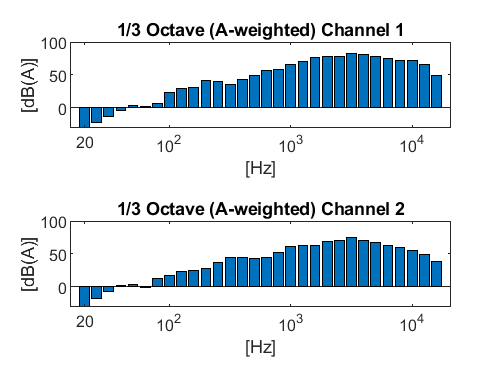

% 1/3 Octave band weighting factors (A-weighted)
A_BandWF = [-50.5, -44.7, -39.4, -34.6, -30.2, ...
    -26.2, -22.5, -19.1, -16.1, -13.4, ...
    -10.9, -8.6, -6.6, -4.8, -3.2, ...
    -1.9, -0.8, 0.0, 0.6, 1.0, ...
    1.2, 1.3, 1.2, 1.0, 0.5, ...
    -0.1, -1.1, -2.5, -4.3, -6.6];
A_BandWF = transpose(A_BandWF);

% Channel 1
% Raw 1/3 Octave SPL
Lp_CH1 = cell2mat(RawData(15:44, 6));
% 1/3 Octave band weighting result
Lp_CH1 = Lp_CH1 + A_BandWF;

% Channel 2
% Raw 1/3 Octave SPL
Lp_CH2 = cell2mat(RawData(15:44, 8));
% 1/3 Octave band weighting result
Lp_CH2 = Lp_CH2 + A_BandWF;

% New figure
figure
% Defining image layout
tiledlayout(2,1);

% 1/3 Octave (A-weighted)
% Channel 1
bar(nexttile, Lp_CH1(1:length(A_BandWF)));
% X-axis ticks and positions
xticks([1 8 18 28]);
xticklabels({'20', '10^2','10^3','10^4'});
% Title
title('1/3 Octave (A-weighted) Channel 1');
% X-axis and y-axis labels
xlabel('[Hz]');
ylabel('[dB(A)]');

% Channel 2
bar(nexttile, Lp_CH2(1:length(A_BandWF)));
% X-axis ticks and positions
xticks([1 8 18 28]);
xticklabels({'20', '10^2','10^3','10^4'});
% Title
title('1/3 Octave (A-weighted) Channel 2');
% X-axis and y-axis labels
xlabel('[Hz]');
ylabel('[dB(A)]');

% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_04', '.png'];
saveas(gcf, SaveFigName);


% Overall level
% Channel 1
ASum = 0;
for index = 1:length(A_BandWF)
    ASum = ASum + 10^(0.1*Lp_CH1(index));
end
Lap_CH1 = 10*log10(ASum)

Lap_CH1 = 87.7940


% Channel 2
ASum = 0;
for index = 1:length(A_BandWF)
    ASum = ASum + 10^(0.1*Lp_CH2(index));
end
Lap_CH2 = 10*log10(ASum)

Lap_CH2 = 78.5395

#### 1/3 Octave to C-weighted sound pressure level

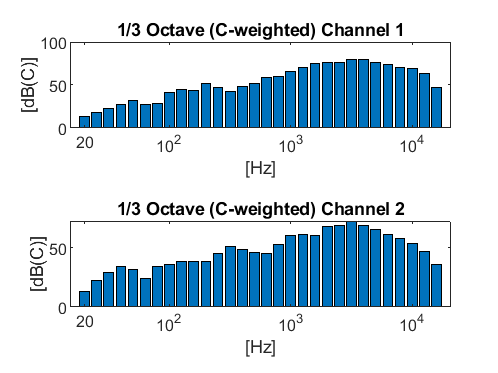

% 1/3 Octave band weighting factors (C-weighted)
C_BandWF = [-6.2, -4.4, -3.0, -2.0, -1.3, ...
    -0.8, -0.5, -0.3, -0.2, -0.1, ...
    0.0, 0.0, 0.0, 0.0, 0.0, ...
    0.0, 0.0, 0.0, 0.0, -0.1, ...
    -0.2, -0.3, -0.5, -0.8, -1.3, ...
    -2.0, -3.0, -4.4, -6.2, -8.5];
C_BandWF = transpose(C_BandWF);

% Channel 1
% Raw 1/3 Octave SPL
Lp_CH1 = cell2mat(RawData(15:44, 6));
% 1/3 Octave band weighting result
Lp_CH1 = Lp_CH1 + C_BandWF;

% Channel 2
% Raw 1/3 Octave SPL
Lp_CH2 = cell2mat(RawData(15:44, 8));
% 1/3 Octave band weighting result
Lp_CH2 = Lp_CH2 + C_BandWF;

% New figure
figure
% Defining image layout
tiledlayout(2,1);

% 1/3 Octave (A-weighted)
% Channel 1
bar(nexttile, Lp_CH1(1:length(C_BandWF)));
% X-axis ticks and positions
xticks([1 8 18 28]);
xticklabels({'20', '10^2','10^3','10^4'});
% Title
title('1/3 Octave (C-weighted) Channel 1');
% X-axis and y-axis labels
xlabel('[Hz]');
ylabel('[dB(C)]');

% Channel 2
bar(nexttile, Lp_CH2(1:length(C_BandWF)));
% X-axis ticks and positions
xticks([1 8 18 28]);
xticklabels({'20', '10^2','10^3','10^4'});
% Title
title('1/3 Octave (C-weighted) Channel 2');
% X-axis and y-axis labels
xlabel('[Hz]');
ylabel('[dB(C)]');

% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_05', '.png'];
saveas(gcf, SaveFigName);


% Overall level
% Channel 1
CSum = 0;
for index = 1:length(C_BandWF)
    CSum = CSum + 10^(0.1*Lp_CH1(index));
end
Lcp_CH1 = 10*log10(CSum)

Lcp_CH1 = 86.1732


% Channel 2
CSum = 0;
for index = 1:length(C_BandWF)
    CSum = CSum + 10^(0.1*Lp_CH2(index));
end
Lcp_CH2 = 10*log10(CSum)

Lcp_CH2 = 76.9677

#### 1/3 Octave to ISO226 loudness

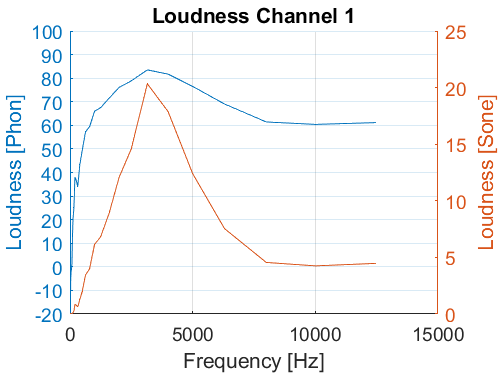

% Frequency
Freq = [20 25 31.5 40 50 63 80 100 125 160 ...
    200 250 315 400 500 630 800 1000 1250 1600 ...
    2000 2500 3150 4000 5000 6300 8000 10000 12500];

% Loudness perception index
af = [0.532 0.506 0.480 0.455 0.432 0.409 0.387 0.367 0.349 0.330 ...
    0.315 0.301 0.288 0.276 0.267 0.259 0.253 0.250 0.246 0.244 ...
    0.243 0.243 0.243 0.242 0.242 0.245 0.254 0.271 0.301];

% Amplitude of the linear transfer function calculated at 1000 Hz
Lu = [-31.6 -27.2 -23.0 -19.1 -15.9 -13.0 -10.3 -8.1 -6.2 -4.5 ...
    -3.1 -2.0 -1.1 -0.4 0.0 0.3 0.5 0.0 -2.7 -4.1 ...
    -1.0 1.7 2.5 1.2 -2.1 -7.1 -11.2 -10.7 -3.1];

% Hearing threshold
Tf = [ 78.5 68.7 59.5 51.1 44.0 37.5 31.5 26.5 22.1 17.9 ...
    14.4 11.4 8.6 6.2 4.4 3.0 2.2 2.4 3.5 1.7 ...
    -1.3 -4.2 -6.0 -5.4 -1.5 6.0 12.6 13.9 12.3];

% Channel 1
% Intercept SPL from 20 to 12500 Hz
OctPhonSPL = transpose(cell2mat(RawData(15:43, 6)));

% Definition of calculation result variables
OctPhon_CH1 = [];

for index = 1:length(OctPhonSPL)
    syms OctPhon;
    % ISO226 loudness calculation
    OctPhon = solve(OctPhonSPL(index) == ((10./af(index))* ...
        log10(4.47E-3 * (10^(0.025*OctPhon) - 1.15) + ...
        (0.4*10^(((Tf(index) + Lu(index))/10)-9))^af(index))) - ...
        Lu(index) + 94);
    % Accurate to 0.0001 and save to the variable
    OctPhon_CH1 = [OctPhon_CH1 double(vpa(OctPhon, 4))]; %#ok<AGROW> 
end

% Transpose the result
OctPhon_CH1 = transpose(OctPhon_CH1);

% Convert result to be nonnegative
OctPhon2Sone_CH1 = OctPhon_CH1;
OctPhon2Sone_CH1(OctPhon2Sone_CH1<0) = 0;

% New figure
figure

% Semilog plot (Phon) (x-axis has log scale)
yyaxis left;
plot(transpose(Freq), OctPhon_CH1)

% Left y-axis control
% Y-axis label
ylabel('Loudness [Phon]')
% X-axis range and y-axis ticks contents
axis([0, 15000, -20, 100])
set(gca, 'ytick', -20:10:100)

% Semilog plot (Sone) (x-axis has log scale)
yyaxis right;
plot(transpose(Freq), phon2sone(OctPhon2Sone_CH1, 'ISO 532-2'))

% Right y-axis control
% Y-axis label
ylabel('Loudness [Sone]')

% Title and X-axis labels
title('Loudness Channel 1')
xlabel('Frequency [Hz]')

% Plots layer properties
grid on
box off

% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_06', '.png'];
saveas(gcf, SaveFigName);

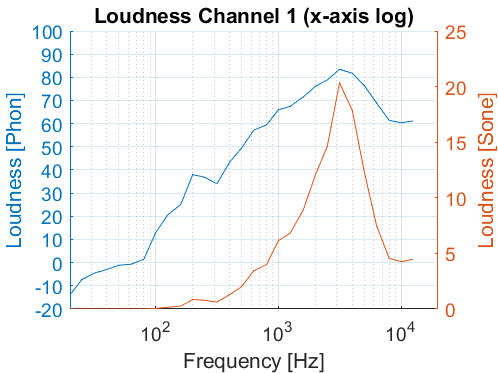


% New figure
figure

% Semilog plot (Phon) (x-axis has log scale)
yyaxis left;
semilogx(transpose(Freq), OctPhon_CH1)

% Left y-axis control
% Y-axis label
ylabel('Loudness [Phon]')
% X-axis range and y-axis ticks contents
axis([0, 20000, -20, 100])
set(gca, 'ytick', -20:10:100)

% Semilog plot (Sone) (x-axis has log scale)
yyaxis right;
semilogx(transpose(Freq), phon2sone(OctPhon2Sone_CH1, 'ISO 532-2'))

% Right y-axis control
% Y-axis label
ylabel('Loudness [Sone]')

% Title and X-axis labels
title('Loudness Channel 1 (x-axis log)')
xlabel('Frequency [Hz]')

% Plots layer properties
grid on
box off

% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_07', '.png'];
saveas(gcf, SaveFigName);

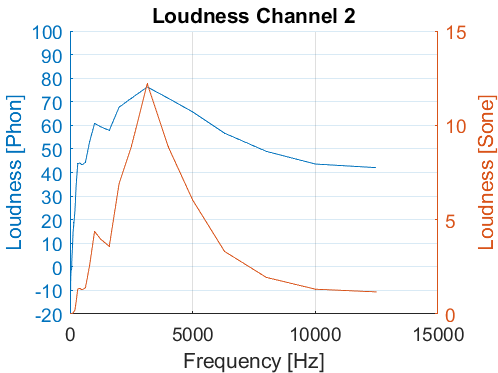


% Channel 2
% Intercept SPL from 20 to 12500 Hz
OctPhonSPL = transpose(cell2mat(RawData(15:43, 8)));

% Definition of calculation result variables
OctPhon_CH2 = [];

for index = 1:length(OctPhonSPL)
    syms OctPhon;
    % ISO226 loudness calculation
    OctPhon = solve(OctPhonSPL(index) == ((10./af(index))* ...
        log10(4.47E-3 * (10^(0.025*OctPhon) - 1.15) + ...
        (0.4*10^(((Tf(index) + Lu(index))/10)-9))^af(index))) - ...
        Lu(index) + 94);
    % Accurate to 0.0001 and save to the variable
    OctPhon_CH2 = [OctPhon_CH2 double(vpa(OctPhon, 4))]; %#ok<AGROW> 
end

% Transpose the result
OctPhon_CH2 = transpose(OctPhon_CH2);

% Convert result to be nonnegative
OctPhon2Sone_CH2 = OctPhon_CH2;
OctPhon2Sone_CH2(OctPhon2Sone_CH2<0) = 0;

% New figure
figure

% Semilog plot (Phon) (x-axis has log scale)
yyaxis left;
plot(transpose(Freq), OctPhon_CH2)

% Left y-axis control
% Y-axis label
ylabel('Loudness [Phon]')
% X-axis range and y-axis ticks contents
axis([0, 15000, -20, 100])
set(gca, 'ytick', -20:10:100)

% Semilog plot (Sone) (x-axis has log scale)
yyaxis right;
plot(transpose(Freq), phon2sone(OctPhon2Sone_CH2, 'ISO 532-2'))

% Right y-axis control
% Y-axis label
ylabel('Loudness [Sone]')

% Title and X-axis labels
title('Loudness Channel 2')
xlabel('Frequency [Hz]')

% Plots layer properties
grid on
box off

% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_08', '.png'];
saveas(gcf, SaveFigName);

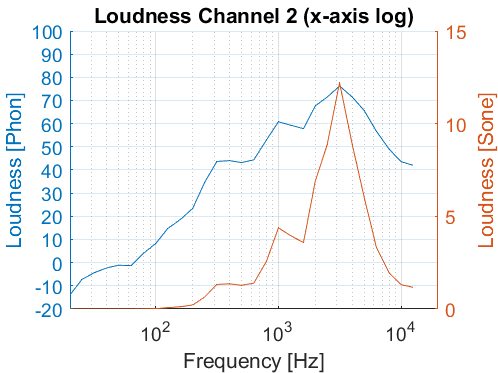


% New figure
figure

% Semilog plot (Phon) (x-axis has log scale)
yyaxis left;
semilogx(transpose(Freq), OctPhon_CH2)

% Left y-axis control
% Y-axis label
ylabel('Loudness [Phon]')
% X-axis range and y-axis ticks contents
axis([0, 20000, -20, 100])
set(gca, 'ytick', -20:10:100)

% Semilog plot (Sone) (x-axis has log scale)
yyaxis right;
semilogx(transpose(Freq), phon2sone(OctPhon2Sone_CH2, 'ISO 532-2'))

% Right y-axis control
% Y-axis label
ylabel('Loudness [Sone]')

% Title and X-axis labels
title('Loudness Channel 2 (x-axis log)')
xlabel('Frequency [Hz]')

% Plots layer properties
grid on
box off

% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_09', '.png'];
saveas(gcf, SaveFigName);

#### Acoustic loudness (MATLAB Toolbox)

% New figure
figure

% https://www.mathworks.com/help/audio/ref/acousticloudness.html
[LN_Sone_CH1, Sone_CH1] = acousticLoudness(cell2mat(RawData(2:Rows, 2)), 16000, 1, ...
    'PressureReference', 2e-5, 'Method', 'ISO 532-2');
[LN_Sone_CH2, Sone_CH2] = acousticLoudness(cell2mat(RawData(2:Rows, 4)), 16000, 1, ...
    'PressureReference', 2e-5, 'Method', 'ISO 532-2');

% ERB scale in ISO532-2
HzBins = erb2hz(1.8:0.1:38.9);

% Plot loudness of channel 1 & 2
semilogx(HzBins, Sone_CH1, HzBins, Sone_CH2)

% X-axis and y-axis labels
xlabel('Frequency [Hz]')
ylabel('Loudness [sone]')
% Title
title('Specific Loudness Channel 1 & 2')
% Legend
legend('Channel 1', 'Channel 2')

% Plots layer properties
grid on
box off

% Show results
LN_Sone_CH1

LN_Sone_CH1 = 107.4521

LN_Sone_CH2

LN_Sone_CH2 = 72.8768

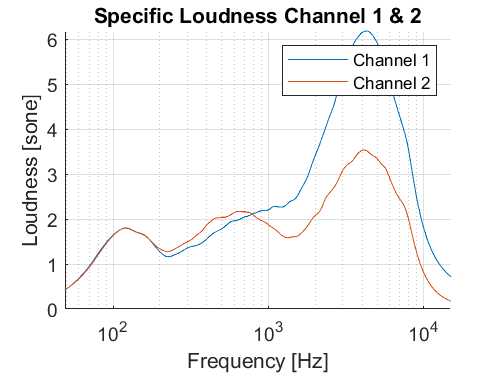


% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_10', '.png'];
saveas(gcf, SaveFigName);

#### Acoustic sharpness (MATLAB Toolbox)

% https://www.mathworks.com/help/audio/ref/acousticsharpness.html
Acum_CH1 = acousticSharpness(cell2mat(RawData(2:Rows, 2)), ...
    16000, 'SoundField', 'diffuse')

Acum_CH1 = 2.9160

Acum_CH2 = acousticSharpness(cell2mat(RawData(2:Rows, 4)), ...
    16000, 'SoundField', 'diffuse')

Acum_CH2 = 2.4141

#### Acoustic fluctuation (MATLAB Toolbox)

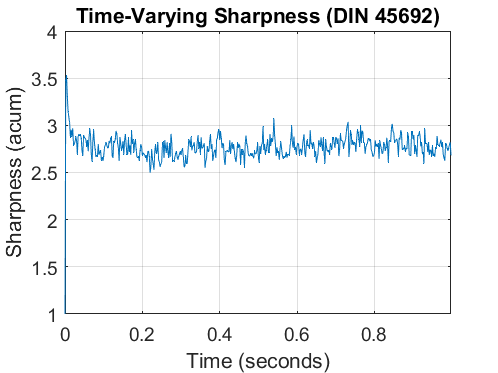

% New figure
figure

% https://www.mathworks.com/help/audio/ref/acousticfluctuation.html
[~, TimeSone_CH1] = acousticLoudness(cell2mat(RawData(2:Rows, 2)), ...
    16000, 'TimeVarying', true);
acousticSharpness(TimeSone_CH1, 'TimeVarying', true)

acousticFluctuation(TimeSone_CH1)

% Show results
F_Time_CH1 = acousticFluctuation(cell2mat(RawData(2:Rows, 2)), 16000);
Vacil_CH1 = mean(F_Time_CH1(1:end,:))

Vacil_CH1 = 3.2400e-06

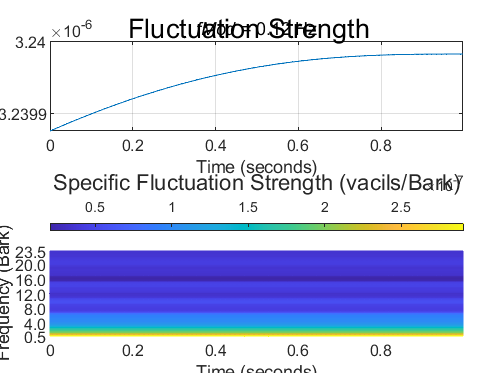


% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_11', '.png'];
saveas(gcf, SaveFigName);


% New figure
figure
[~, TimeSone_CH2] = acousticLoudness(cell2mat(RawData(2:Rows, 4)), ...
    16000, 'TimeVarying', true);
acousticSharpness(TimeSone_CH2, 'TimeVarying', true)
acousticFluctuation(TimeSone_CH2)

% Show results
F_Time_CH2 = acousticFluctuation(cell2mat(RawData(2:Rows, 2)), 16000);
Vacil_CH2 = mean(F_Time_CH2(1:end,:))

Vacil_CH2 = 3.2400e-06

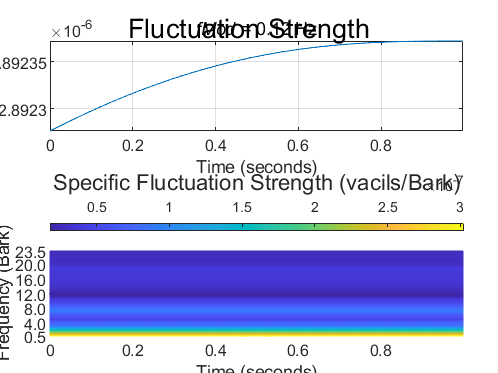


% Save the figure
SaveFigName = ['.\04_AdvFigure\', BasicName, '_12', '.png'];
saveas(gcf, SaveFigName);

#### Acoustic roughness (MATLAB Toolbox)

% https://www.mathworks.com/help/audio/ref/acousticroughness.html
Asper_CH1 = mean(acousticRoughness(cell2mat(RawData(2:Rows, 2)), 16000))

Asper_CH1 = 0.0813

Asper_CH2 = mean(acousticRoughness(cell2mat(RawData(2:Rows, 4)), 16000))

Asper_CH2 = 0.0877

#### Psychoacoustic annoyance

% Psychoacoustic annoyance calculaton
PA_CH1 = psy_annoyance(LN_Sone_CH1, Acum_CH1, Vacil_CH1, Asper_CH1)

PA_CH1 = 172.3114

PA_CH2 = psy_annoyance(LN_Sone_CH2, Acum_CH2, Vacil_CH2, Asper_CH2)

PA_CH2 = 96.1365

#### Save the results

TXTFileName = ['.\06_Results\', BasicName, '.txt'];

FileID = fopen(TXTFileName,'w');

fprintf(FileID,'\tChannel 1\tChannel 2\n');
fprintf(FileID,'Loudness\t%f\t%f\n', LN_Sone_CH1, LN_Sone_CH2);
fprintf(FileID,'Sharpness\t%f\t%f\n', Acum_CH1, Acum_CH2);
fprintf(FileID,'Fluctuation\t%f\t%f\n', Vacil_CH1, Vacil_CH2);
fprintf(FileID,'Roughness\t%f\t%f\n', Asper_CH1, Asper_CH2);
fprintf(FileID,'Annoyance\t%f\t%f\n', PA_CH1, PA_CH2);

fclose(FileID);


## Universal calculation

#### Equal-Loudness Curves

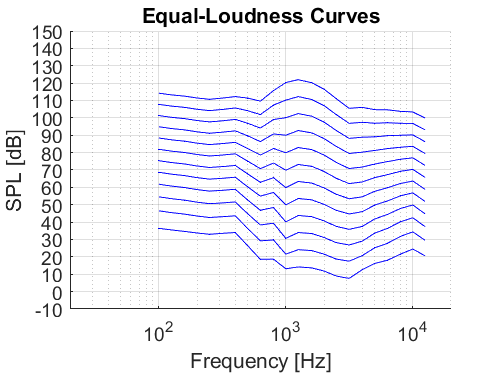

% New figure
figure

% Loudness values (Phon)
LoudnessPhon = 10:10:120;

% Plot the equal loudness contour at the above loudness
for LoudnessPhon = LoudnessPhon
    % Call the function to calculate the result
    [PhonSPL, PhonFreq] = equal_loudness(LoudnessPhon, 'Chinese');
    % Semilog plot (x-axis has log scale)
    semilogx(PhonFreq, PhonSPL, 'color', 'b')
    
    % Title
    title('Equal-Loudness Curves')
    % X-axis and y-axis labels
    xlabel('Frequency [Hz]')
    ylabel('SPL [dB]')
    % X-axis range and y-axis ticks contents
    axis([20, 20000, -10, 150])
    set(gca, 'ytick', -10:10:150)
    % Plots layer properties
    hold on
    grid on
    box off
end

% Save the figure
SaveFigName = ['.\05_UniFigure\', 'Equal_Loudness_Curves', '.png'];
saveas(gcf, SaveFigName);

#### Pure Tone Threshold Audiometry (PTA)

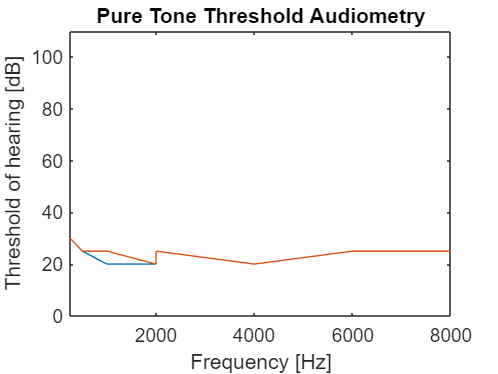

% http://hearing.sw-tl.com/

% New figure
figure

% Test frequency
PTA_Freq = [250 500 1000 2000 2000 4000 6000 8000];

% Test data
PTA_HL_Right = [30 25 20 20 25 20 25 25];
PTA_HL_Left = [30 25 25 20 25 20 25 25];

% % Plot the Pure Tone Threshold Audiometry
plot(PTA_Freq, PTA_HL_Right, PTA_Freq, PTA_HL_Left);
% Title
title('Pure Tone Threshold Audiometry')
% X-axis and y-axis labels
xlabel('Frequency [Hz]')
ylabel('Threshold of hearing [dB]')
% X-axis range and y-axis ticks contents
axis([250, 8000, 0, 110])

## Functions

#### equal_loudness -- ISO226 loudness calculation

function [Equal_SPL, Equal_Freq] = equal_loudness(Equal_Phon, Method)

if strcmp(Method, 'ISO226') == 1
    % Frequency
    Freq = [20 25 31.5 40 50 63 80 100 125 160 ...
        200 250 315 400 500 630 800 1000 1250 1600 ...
        2000 2500 3150 4000 5000 6300 8000 10000 12500];
    
    % Loudness perception index
    af = [0.532 0.506 0.480 0.455 0.432 0.409 0.387 0.367 0.349 0.330 ...
        0.315 0.301 0.288 0.276 0.267 0.259 0.253 0.250 0.246 0.244 ...
        0.243 0.243 0.243 0.242 0.242 0.245 0.254 0.271 0.301];
    
    % Amplitude of the linear transfer function calculated at 1000 Hz
    Lu = [-31.6 -27.2 -23.0 -19.1 -15.9 -13.0 -10.3 -8.1 -6.2 -4.5 ...
        -3.1 -2.0 -1.1 -0.4 0.0 0.3 0.5 0.0 -2.7 -4.1 ...
        -1.0 1.7 2.5 1.2 -2.1 -7.1 -11.2 -10.7 -3.1];
    
    % Hearing threshold
    Tf = [78.5 68.7 59.5 51.1 44.0 37.5 31.5 26.5 22.1 17.9 ...
        14.4 11.4 8.6 6.2 4.4 3.0 2.2 2.4 3.5 1.7 ...
        -1.3 -4.2 -6.0 -5.4 -1.5 6.0 12.6 13.9 12.3];

elseif strcmp(Method, 'Chinese') == 1
    % Frequency
    Freq = [100 125 160 200 250 315 400 500 630 800 1000 ... 
        1250 1600 2000 2500 3150 4000 5000 6300 8000 10000 12500];

    % Loudness perception index
    af = [0.389 0.388 0.387 0.386 0.385 0.383 0.381 0.346 0.323 0.301 0.247 ... 
        0.256 0.260 0.264 0.273 0.289 0.291 0.320 0.336 0.364 0.380 0.367];
    
    % Amplitude of the linear transfer function calculated at 1000 Hz
    Lu = [-3.5 -2.5 -1.7 -0.6 0.2 -0.4 -1.2 1.4 4.5 -0.1 0.0 ... 
        -2.6 -1.2 2.1 6.8 11.0 10.3 9.6 8.7 8.1 7.7 11.8];
    
    % Hearing threshold
    Tf = [24.1 23.7 22.9 22.6 22.2 23.1 23.5 16.6 7.9 8.0 7.4 ... 
        6.6 5.9 4.4 1.2 -0.7 6.7 8.6 8.8 10.2 13.3 12.0];

end
% Loudness (Phon)
Ln = Equal_Phon;

% Definition of standard H equal loudness curve
Af = 4.47E-3 * (10.^(0.025*Ln) - 1.15) + (0.4*10.^(((Tf+Lu)/10)-9 )).^af;
Lp = ((10./af).*log10(Af)) - Lu + 94;

% Function return value
Equal_SPL = Lp;  
Equal_Freq = Freq;

end


#### Time domain to frequency domain (1/3 Octave)

function [Oct_Fc, Oct_SPL, Freq_SPL, Total_SPL] = tf_octave(TDData, Frequency)

% Reference sound pressure (in air)
Pref = 2e-5;

% Data input
[TDRows, ~] = size(TDData);

% Recording length of discrete-time signals
NFFT = 2^nextpow2(TDRows-1);

% Fourier transform
OctAmp = fft(detrend(TDData(:,2), 0), NFFT);

% Frequency vectors
FreqVector = (0:NFFT-1) / (NFFT-1) * Frequency;

% Take half according to symmetry
Half_OctAmp = OctAmp(1:NFFT/2)*2/NFFT;
Half_FreqVector = FreqVector(1:NFFT/2);

% Energy in the frequency domain
OctAmp_Energy = abs(Half_OctAmp);

% Calculation of SPL of the spectrum
Freq_SPL = 20 * log10(OctAmp_Energy/Pref);

% Calculation of total SPL
FreqSelect = OctAmp_Energy(Half_FreqVector>=20 & Half_FreqVector<=16000);
Total_SPL = 20 * log10(sqrt(sum(FreqSelect.^2))/Pref);

% Defining the centre frequency of the 1/3 octave
Oct_Fc = [20 25 31.5 40 50 63 80 100 125 160 ... 
    200 250 315 400 500 630 800 1000 1250 1600 ... 
    2000 2500 3150 4000 5000 6300 8000 10000 12500 16000];

% Lower and upper limit frequencies
Fc_Lower = round(Oct_Fc/(2^(1/6)));
Fc_Upper = round(Oct_Fc*(2^(1/6)));
Fc_Upper(end) = FreqVector(end);

% The position of lower and upper limit frequencies
Num_Lower = round(Fc_Lower*2/Frequency*(NFFT/2-1) + 1);
Num_Upper = round(Fc_Upper*2/Frequency*(NFFT/2-1) + 1);
Num_Center = length(Oct_Fc);

% Calculating 1/3 octave
for index = 1:Num_Center
    OctExt = zeros(1,NFFT);
    OctExt(Num_Lower(index) : Num_Upper(index)) = ...
        OctAmp(Num_Lower(index) : Num_Upper(index));
    OctExt(end-Num_Upper(index)+1 : end-Num_Lower(index)+1) = ...
        OctAmp(end-Num_Upper(index)+1 : end-Num_Lower(index)+1);
    InvOctExt = ifft(OctExt);
    OctBand_Pe(index) = sqrt(var(real(InvOctExt(1:NFFT)))); %#ok<AGROW> 
end

% Calculation of the SPL at the centre frequency
Oct_SPL = 20 * log10(OctBand_Pe/Pref);

end


#### Segmented SPL calculation

function Frame_SPL = spl_segcal(TDData, Frequency, Frame_Length )

% Reference sound pressure (in air)
Pref = 2e-5;

% Number of discrete points per signal frame
N_perFrame = Frame_Length*Frequency/1000;

% Calculation of effective sound pressure
Pe_per = 0;
for i = 1:N_perFrame
   Pe_per = Pe_per + TDData(i)^2;
end
Pe_Seg = sqrt(Pe_per/N_perFrame);

% Calculation of SPL
Frame_SPL = 20*log10(Pe_Seg/Pref);

end


#### Calculate psychoacoustic annoyance

function [PA] = psy_annoyance(N_Sone, S_Acum, F_Vacil, R_Asper)

% Describing the effects of sharpness
W_s = (S_Acum - 1.75) * 0.25*log10(N_Sone + 10);
% Describing the influence of fluctuation strength and roughness
W_fr = 2.18/(N_Sone^0.4) * (0.4*F_Vacil + 0.6*R_Asper);

% Psychoacoustic annoyance
PA = N_Sone * (1 + sqrt(W_s^2 + W_fr^2));

end
